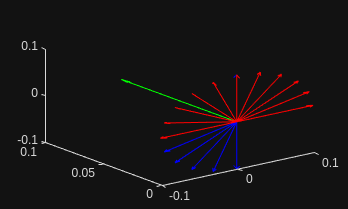

pa = [0 0 0];
pb = [0 0 0];
qa = quaternion([1 0 0 0]);
qb = quaternion([0 0 1 0]);
Ra = qa.rotmat("frame");
Rb = qb.rotmat("frame");

plot_frame(pa,Ra,1);
plot_frame(pb,Rb,1);

qr = qa*qb.conj();
Rc = qa.slerp(qb,0.1).rotmat("frame");

for i = 1:10
    plot_frame(pa,qa.slerp(qb,i*0.1).rotmat("frame"),1);
end